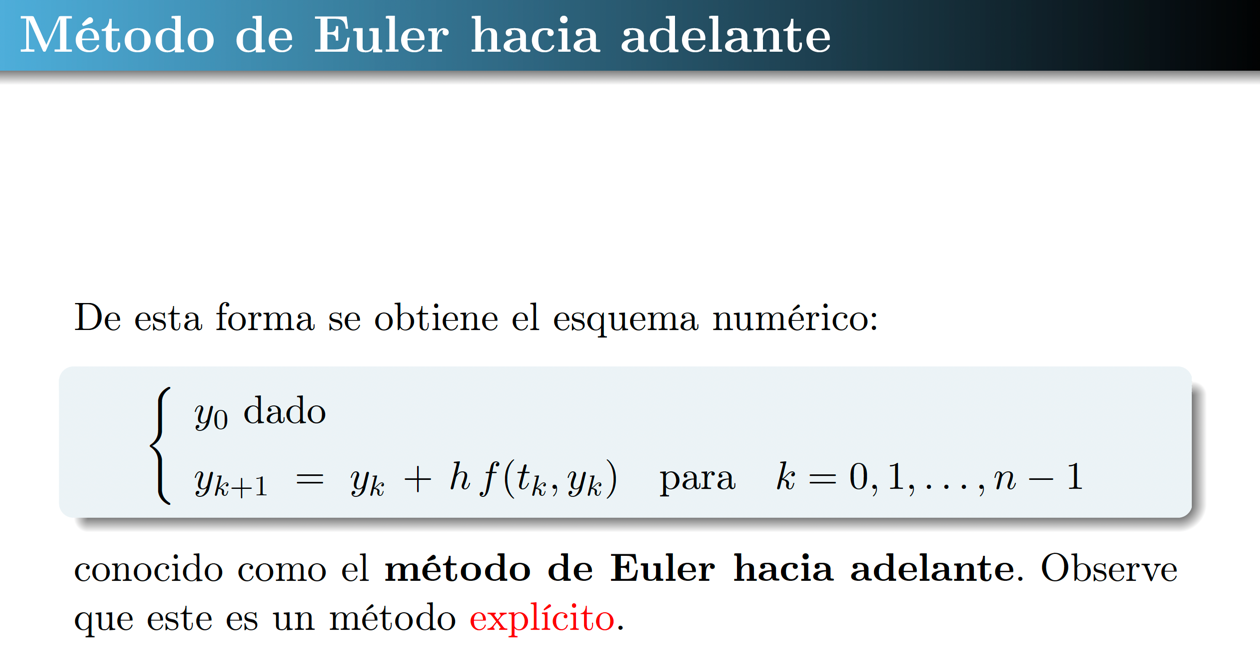

**Ejemplo:**

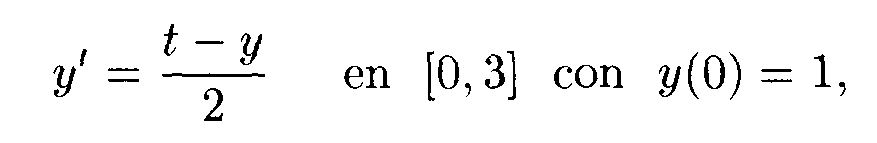

f = @(t,y) (t-y)/2; 
a = 0; b = 3;
y0 = 1;


T = Euler(f, a, b, y0, 3)

T =          0    1.0000
    1.0000    0.5000
    2.0000    0.7500
    3.0000    1.3750



% Solucion exacta del PVI:
y = @(t) 3*exp(-t./2) - 2 + t;

yImExactas = y(T(:,1))

yImExactas =     1.0000
    0.8196
    1.1036
    1.6694


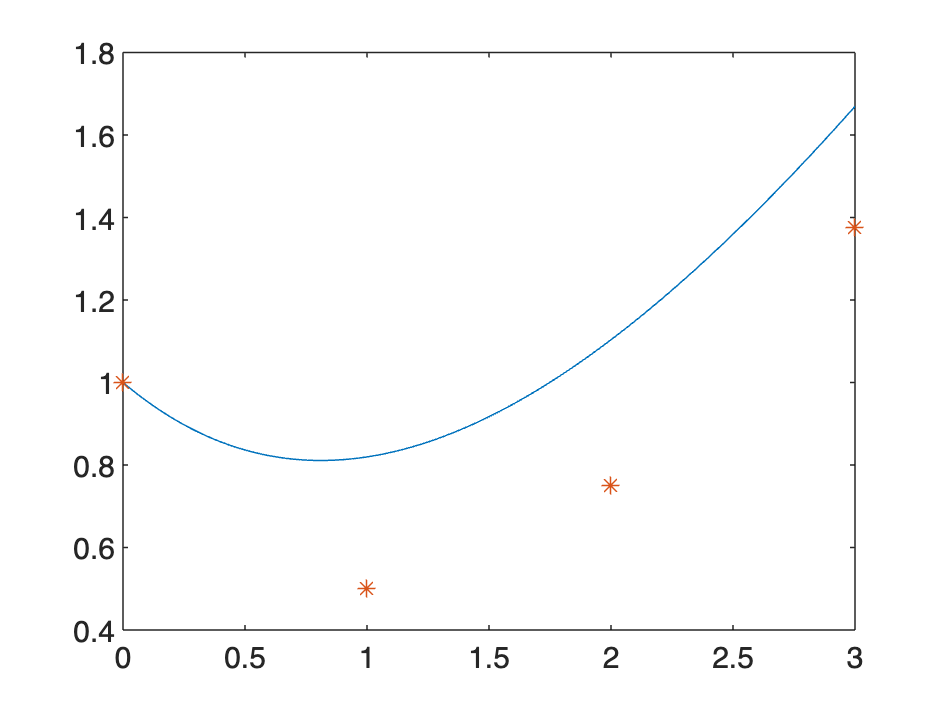


% Veamos graficamente:

X = linspace(a, b, 100);
Y = y(X);

plot(X,Y, T(:,1), T(:,2), '*')

**Runge-Kutta 2:**

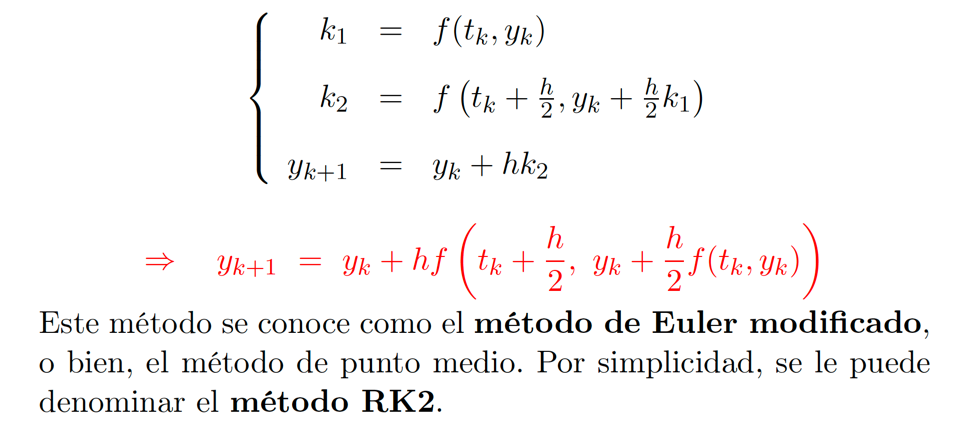

% Ahora con el metodo de Heun:

T = Heun(f, a, b, y0, 3)

T =          0    1.0000
    1.0000    0.8750
    2.0000    1.1719
    3.0000    1.7324



% Solucion exacta del PVI:
y = @(t) 3*exp(-t./2) - 2 + t;

yImExactas = y(T(:,1))

yImExactas =     1.0000
    0.8196
    1.1036
    1.6694


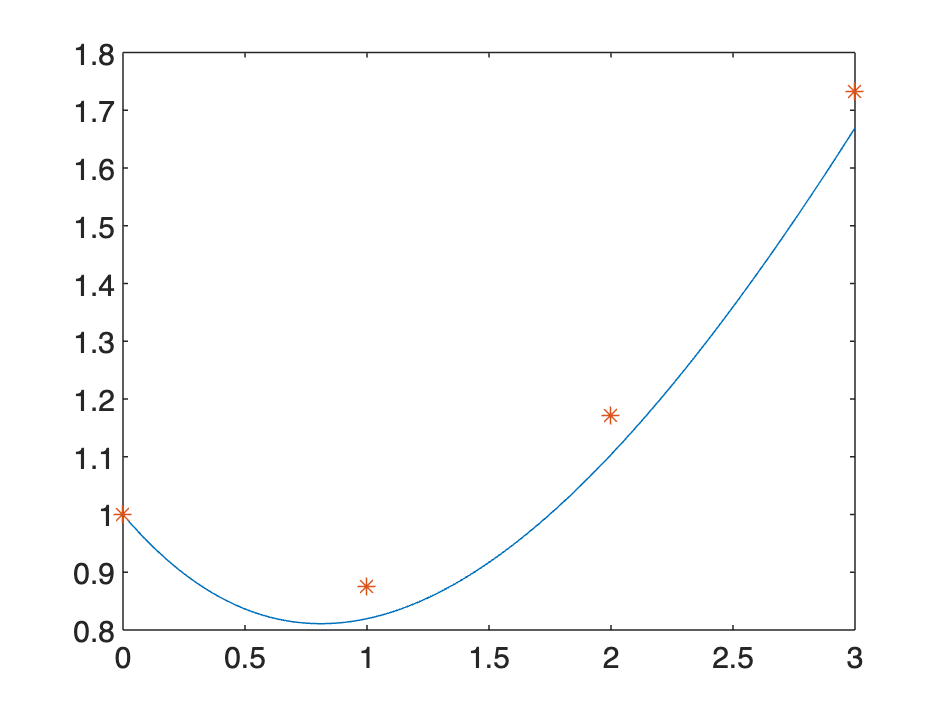


% Veamos graficamente:

X = linspace(a, b, 100);
Y = y(X);

plot(X,Y, T(:,1), T(:,2), '*')

% Ahora con el metodo de Runge-Kutta 2:

T = RK2(f, a, b, y0, 3)

T =          0    1.0000
    1.0000    0.8750
    2.0000    1.1719
    3.0000    1.7324



% Solucion exacta del PVI:
y = @(t) 3*exp(-t./2) - 2 + t;

yImExactas = y(T(:,1))

yImExactas =     1.0000
    0.8196
    1.1036
    1.6694



% Veamos graficamente:

X = linspace(a, b, 100);
Y = y(X);

plot(X,Y, T(:,1), T(:,2), '*')

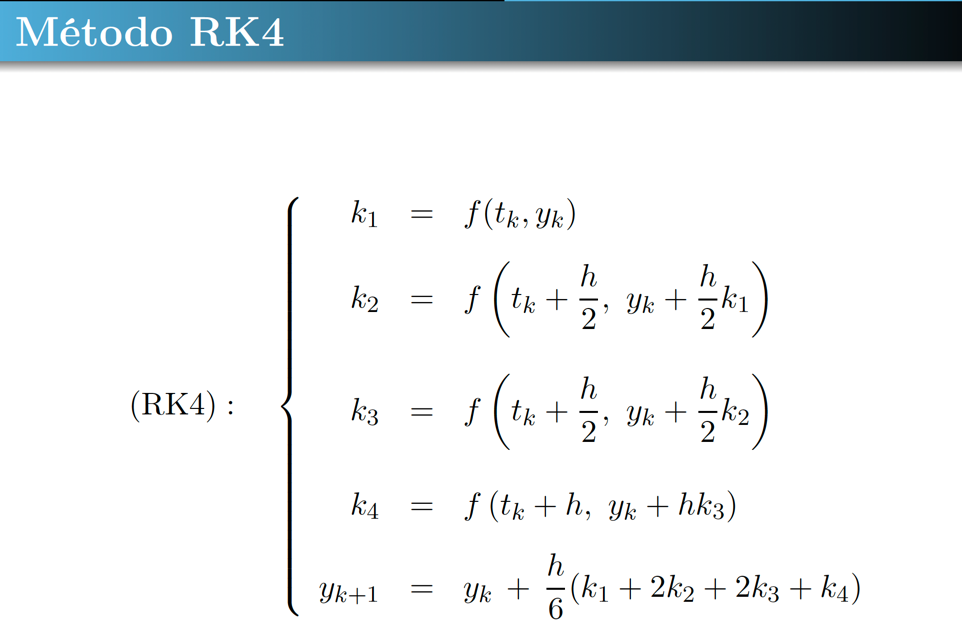

% Ahora con el metodo de Runge-Kutta 4:

T = RK4(f, a, b, y0, 3)

T =          0    1.0000
    1.0000    0.8203
    2.0000    1.1045
    3.0000    1.6702



% Solucion exacta del PVI:
y = @(t) 3*exp(-t./2) - 2 + t;

yImExactas = y(T(:,1))

yImExactas =     1.0000
    0.8196
    1.1036
    1.6694


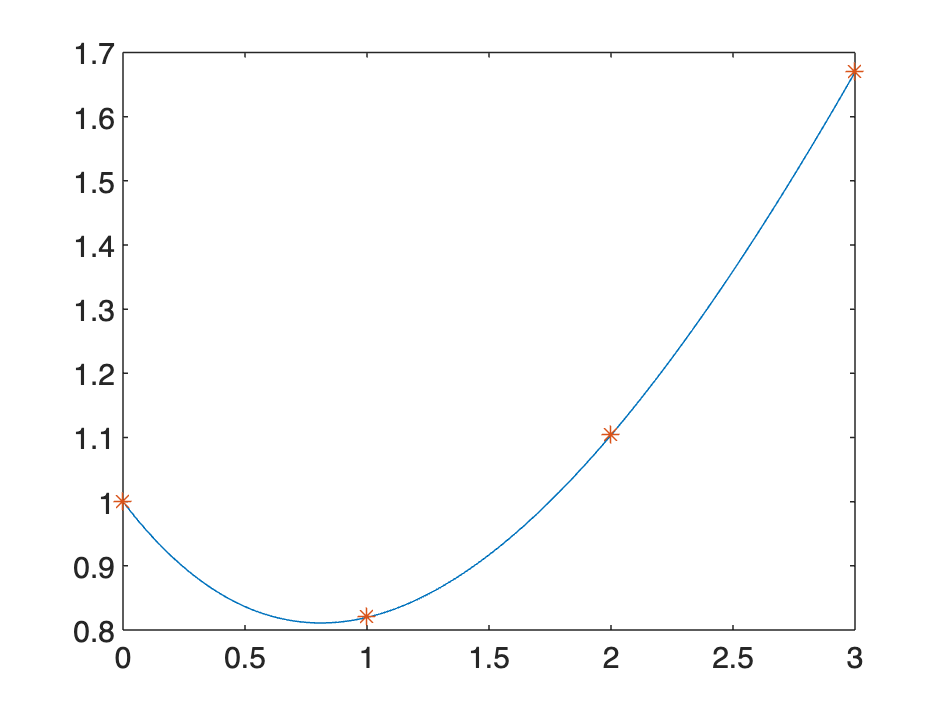


% Veamos graficamente:

X = linspace(a, b, 100);
Y = y(X);

plot(X,Y, T(:,1), T(:,2), '*')

function T = Euler(f, a, b, y0, N)
% Inputs: f funcion, [a,b] intervalo, y0 = y(t0), N # intervalos
% Output: T = [t' y']: t = la particion en t, y = aprox de y(t)

h = (b-a)/N; % paso
t = a:h:b; % particion uniforme 

y(1) = y0; % defino la primer entrada del vector 'y' 


for k = 1:N
    y(k+1) = y(k) + h*f(t(k), y(k));
end

T = [t', y']; % Tabla con columnas t, y

end

% Metodo de Heun

function T = Heun(f, a, b, y0, N)
% Inputs: f funcion, [a,b] intervalo, y0 = y(t0), N # intervalos
% Output: T = [t' y']: t = la particion en t, y = aprox de y(t)

h = (b-a)/N; % paso
t = a:h:b; % particion uniforme 

y(1) = y0; % defino la primer entrada del vector 'y' 


for k = 1:N
    y(k+1) = y(k) + h*f(t(k), y(k)); % paso 'techo'
    y(k+1) = y(k) + (h/2)*(f(t(k), y(k)) + f(t(k+1), y(k+1)));
end

T = [t', y']; % Tabla con columnas t, y

end

% Metodo de Runge-Kutta 2

function T = RK2(f, a, b, y0, N)
% Inputs: f funcion, [a,b] intervalo, y0 = y(t0), N # intervalos
% Output: T = [t' y']: t = la particion en t, y = aprox de y(t)

h = (b-a)/N; % paso
t = a:h:b; % particion uniforme 

y(1) = y0; % defino la primer entrada del vector 'y' 


for k = 1:N
    k1 = f(t(k), y(k));
    k2 = f(t(k)+h/2, y(k)+ h*k1/2); 
    y(k+1) = y(k) + h*k2;
end

T = [t', y']; % Tabla con columnas t, y

end

% Metodo de Runge-Kutta 4

function T = RK4(f, a, b, y0, N)
% Inputs: f funcion, [a,b] intervalo, y0 = y(t0), N # intervalos
% Output: T = [t' y']: t = la particion en t, y = aprox de y(t)

h = (b-a)/N; % paso
t = a:h:b; % particion uniforme 

y(1) = y0; % defino la primer entrada del vector 'y' 


for k = 1:N
    k1 = f(t(k), y(k));
    k2 = f(t(k)+h/2, y(k)+ h*k1/2); 
    k3 = f(t(k)+h/2, y(k)+ h*k2/2);
    k4 = f(t(k)+h, y(k) + h*k3);
    y(k+1) = y(k) + (h/6)*(k1 +2*k2 +2*k3 +k4) ;
end

T = [t', y']; % Tabla con columnas t, y

end












